%%% Coded by Santiago Caballero Rosas %%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Parámetros
beta = 0.1; % Tasa de infección
gamma_H = 0.02; % Tasa de recuperación en humanos

% Valores iniciales
S_H0 = 1000;
I_H0 = 1; % pequeña infección inicial
T_H0 = 0;
S_G0 = 500;
I_G0 = 1; % pequeña infección inicial

% Simulación de las dinámicas de la población
t_max = 100;
S_H_vals = zeros(1, t_max);
I_H_vals = zeros(1, t_max);
T_H_vals = zeros(1, t_max);
S_G_vals = zeros(1, t_max);
I_G_vals = zeros(1, t_max);

% Valores iniciales
S_H_vals(1) = S_H0;
I_H_vals(1) = I_H0;
T_H_vals(1) = T_H0;
S_G_vals(1) = S_G0;
I_G_vals(1) = I_G0;

% Simulación
for t = 1:t_max-1
    dS_H = -beta * I_G_vals(t) * S_H_vals(t);
    dI_H = beta * I_G_vals(t) * S_H_vals(t) - gamma_H * I_H_vals(t);
    dT_H = gamma_H * I_H_vals(t);
    dS_G = -beta * I_G_vals(t) * S_G_vals(t);
    dI_G = beta * I_G_vals(t) * S_G_vals(t);

    S_H_vals(t+1) = S_H_vals(t) + dS_H;
    I_H_vals(t+1) = I_H_vals(t) + dI_H;
    T_H_vals(t+1) = T_H_vals(t) + dT_H;
    S_G_vals(t+1) = S_G_vals(t) + dS_G;
    I_G_vals(t+1) = I_G_vals(t) + dI_G;
end

% Graficar las dinámicas de la población para ver la estabilidad
figure;

% Análisis de puntos de equilibrio y estabilidad
syms S_H I_H T_H S_G I_G
eq1 = -beta * I_G * S_H == 0;
eq2 = beta * I_G * S_H - gamma_H * I_H == 0;
eq3 = gamma_H * I_H == 0;
eq4 = -beta * I_G * S_G == 0;
eq5 = beta * I_G * S_G == 0;

solutions = solve([eq1, eq2, eq3, eq4, eq5], [S_H, I_H, T_H, S_G, I_G]);
S_H_eq = double(solutions.S_H);
I_H_eq = double(solutions.I_H);
T_H_eq = double(solutions.T_H);
S_G_eq = double(solutions.S_G);
I_G_eq = double(solutions.I_G);

fprintf('Puntos de Equilibrio:\n');

Puntos de Equilibrio:


disp([S_H_eq, I_H_eq, T_H_eq, S_G_eq, I_G_eq]);

     0     0     0     0     0




% Recalcular la matriz jacobiana en los puntos de equilibrio obtenidos
J = [0, 0, 0, 0, -beta * S_H_eq; 
     0, -gamma_H, 0, 0, beta * S_H_eq; 
     0, gamma_H, 0, 0, 0; 
     0, 0, 0, 0, -beta * S_G_eq; 
     0, 0, 0, 0, beta * S_G_eq];

eig_vals = eig(J);

fprintf('Eigenvalores de la matriz Jacobiana:\n');

Eigenvalores de la matriz Jacobiana:


disp(eig_vals);

         0
         0
   -0.0200
         0
         0




fprintf('Interpretación de los eigenvalores:\n');

Interpretación de los eigenvalores:


for i = 1:length(eig_vals)
    if real(eig_vals(i)) < 0
        fprintf('Eigenvalor %d: %.2f (estable)\n', i, eig_vals(i));
    elseif real(eig_vals(i)) > 0
        fprintf('Eigenvalor %d: %.2f (inestable)\n', i, eig_vals(i));
    else
        fprintf('Eigenvalor %d: %.2f (neutro)\n', i, eig_vals(i));
    end
end

Eigenvalor 1: 0.00 (neutro)
Eigenvalor 2: 0.00 (neutro)


Eigenvalor 3: -0.02 (estable)


Eigenvalor 4: 0.00 (neutro)
Eigenvalor 5: 0.00 (neutro)


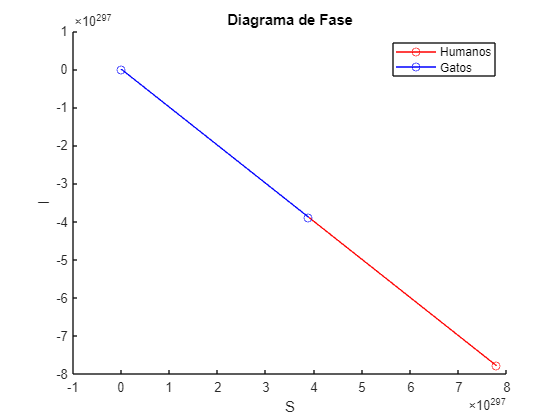


% Diagramas de Fase
figure;
hold on;
plot(S_H_vals, I_H_vals, 'ro-', 'DisplayName', 'Humanos');
plot(S_G_vals, I_G_vals, 'bo-', 'DisplayName', 'Gatos');
xlabel('S');
ylabel('I');
title('Diagrama de Fase');
legend;
hold off;

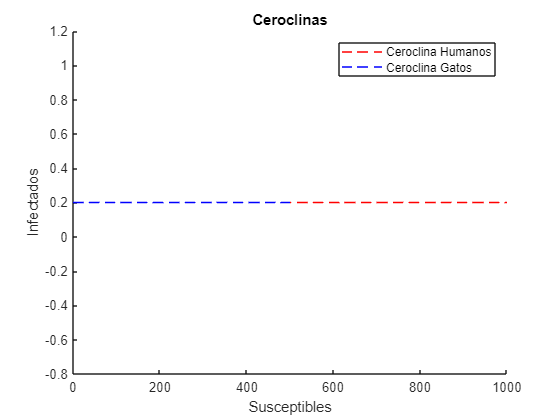


% Ceroclinas
BS_vec = 0:0.01:S_H0;
PS_vec = 0:0.01:S_G0;

figure;
hold on;
ceroclina_H = gamma_H / beta;
plot(BS_vec, ceroclina_H * ones(size(BS_vec)), 'r--', 'DisplayName', 'Ceroclina Humanos');
ceroclina_G = gamma_H / beta;
plot(PS_vec, ceroclina_G * ones(size(PS_vec)), 'b--', 'DisplayName', 'Ceroclina Gatos');
xlabel('Susceptibles');
ylabel('Infectados');
title('Ceroclinas');
legend;
hold off;

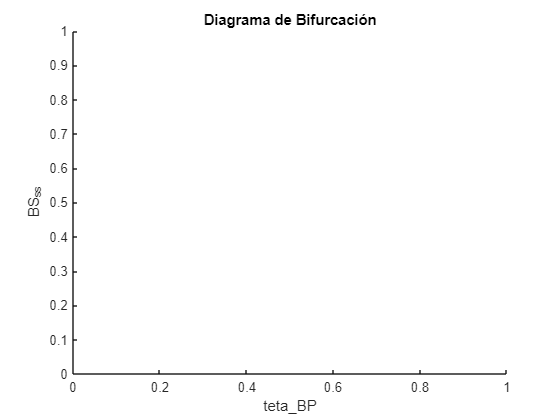


% Diagramas de Bifurcación
teta_BP_crit = -(beta * S_H0^2 - gamma_H * S_H0) / (gamma_H * S_H0);

figure;
hold on;

for teta_BP = 0.5:0.1:teta_BP_crit + 1
    % Calcular puntos de equilibrio para cada valor de teta_BP
    BSss = solBS(beta, gamma_H, teta_BP, S_H0, S_G0);
    PSss = solPS(beta, gamma_H, teta_BP, S_H0, S_G0);
    
    % Evaluar estabilidad
    J1 = jacobian([BSss; PSss], [S_H, S_G]);
    eig_vals = double(eig(J1));
    
    if all(real(eig_vals) < 0)
        S1 = 1;
    else
        S1 = 0;
    end
    
    % Graficar
    if S1 == 1
        scatter(teta_BP, BSss(1), 'ok', 'filled');
    else
        scatter(teta_BP, BSss(1), 'ok');
    end
end

xlabel('teta\_BP');
ylabel('BS_{ss}');
title('Diagrama de Bifurcación');
hold off;


% Funciones para calcular los puntos de equilibrio

function BSss = solBS(beta, gamma_H, teta_BP, S_H0, S_G0)
    % Ejemplo de implementación del cálculo del punto de equilibrio BSss basado en los parámetros
    % La implementación específica depende del modelo que estés utilizando
    % Esta es una implementación hipotética y debe ser ajustada según tu modelo
    S_H_eq = S_H0; % Este es solo un valor inicial
    I_H_eq = teta_BP / (beta * S_H0); % Esta es una suposición, cambia según tu modelo
    T_H_eq = gamma_H * I_H_eq; % También una suposición, ajusta según tu modelo
    BSss = [S_H_eq; I_H_eq; T_H_eq]; % Modifica esta línea con tu cálculo específico
end

function PSss = solPS(beta, gamma_H, teta_BP, S_H0, S_G0)
    % Ejemplo de implementación del cálculo del punto de equilibrio PSss basado en los parámetros
    % La implementación específica depende del modelo que estés utilizando
    % Esta es una implementación hipotética y debe ser ajustada según tu modelo
    S_G_eq = S_G0; % Este es solo un valor inicial
    I_G_eq = teta_BP / (beta * S_G0); % Esta es una suposición, cambia según tu modelo
    PSss = [S_G_eq; I_G_eq]; % Modifica esta línea con tu cálculo específico
end

